clear
DH.theta = [0 0 0];
DH.d = [4 0 0];
DH.a = [0 3 0];
DH.alpha = [-pi/2 pi/2 0];


DH.type = [0,0,1];
cc = 0;

for i = 1:3
    if DH.type(i) ==0
        L(i) = Revolute('d', DH.d(i),'a', DH.a(i),'alpha', DH.alpha(i))
        cc= cc+1;
    else
        M(i-cc) = Prismatic('theta', DH.theta(i),'a', DH.a(i),'alpha', DH.alpha(i))
    end
end

 
L = 
Revolute(std): theta=q, d=4, a=0, alpha=-1.5708, offset=0
 
L = 
Revolute(std):  theta=q1   d=4           a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=3           alpha=1.571       offset=0          


 
M = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=0



M.qlim = [1 5]

 
M = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=0


rob = SerialLink(L+M,'name','rob')

 
rob = 
 
rob:: 3 axis, RRP, stdDH, slowRNE                                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|    -1.5708|          0|
|  2|         q2|          0|          3|     1.5708|          0|
|  3|          0|         q3|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


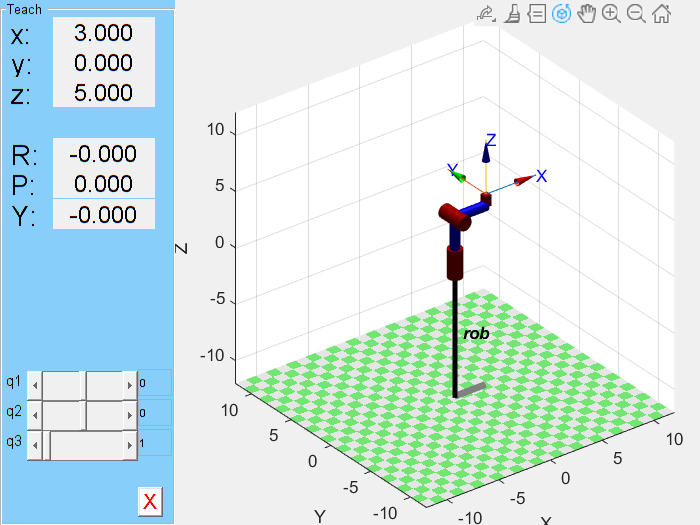

%rob.teach

%rob.plot([0 0 2],'wrist','arrow')
set(gcf,'Visible','on')
rob.teach

L(1).sym

 
ans = 
Revolute(std): theta=q, d=0, a=0, alpha=-pi/2, offset=0
